## **Description of the daily puzzle:**

**Daily Puzzle (LEGO IDEAS, **[**https://ideas.lego.com/projects/3904ad33-709e-4733-83cd-29e28762a7da**](https://ideas.lego.com/projects/3904ad33-709e-4733-83cd-29e28762a7da)**)**

**Designer: bsx1990(张宁) **[**https://www.instagram.com/bsx1990/**](https://www.instagram.com/bsx1990/)

**What is DailyPuzzle**

This is Daily Puzzle, my original puzzle toy.

You can make a baseplate and 9 block pieces, and then use them to show every date in your life.

In fact, there is more than one solution for every day.

**How to play**

The board has the numbers of months / days / weeks, we should find out the  date we want to show and use the 9 pieces to cover the other numbers so  that we can see the date after we finished the puzzle.

**Why I believe it would make a great LEGO set**

Daily Puzzle makes the date becomes a puzzle for every day. I wrote an  efficient program and verified all the dates. I'm sure that every date  has more than one solution.

I think it was a great LEGO set as it combine the calendar and puzzle and LEGO.

**DailyPuzzle Hints for everyday**

I'm going to publish some hints for everyday on [my Instagram](https://www.instagram.com/bsx1990/). You can follow it if you need the hints.

I hope you can love it and support it.

* Test in Matlab R2021b, with Ghostscript 9.54.0 (https://github.com/ArtifexSoftware/ghostpdl-downloads/releases)

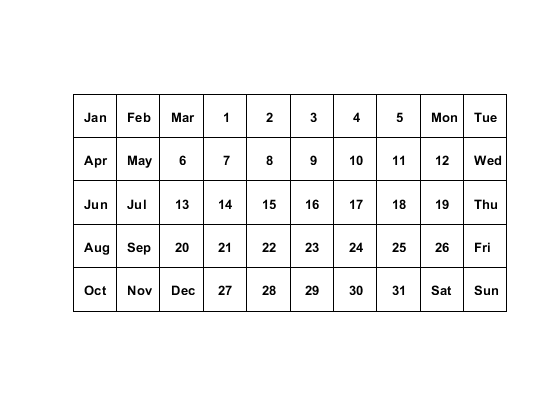

clear

time=clock;
seed=round(sum(time(4:6))*sum(time(2:3))/10);
rng(seed);

%% Frame shape
FrameDefault = false(5,10);

Text_Frame = {'Jan','Feb','Mar','1','2','3','4','5','Mon','Tue'; 'Apr','May','6','7','8','9','10','11','12','Wed';
        'Jun','Jul','13','14','15','16','17','18','19','Thu'; 'Aug','Sep','20','21','22','23','24','25','26','Fri';
        'Oct','Nov','Dec','27','28','29','30','31','Sat','Sun'};

if true
    figure;
    temp_FrameDefault = [flip(~FrameDefault), ones(size(FrameDefault,1),1); ones(1,size(FrameDefault,2)+1)];
    H1 = pcolor(temp_FrameDefault);
    colormap(gray(2));
    axis equal
    ylim([1 6])
    set(gca, 'xticklabel', [], 'yticklabel', [])
    labelTable(FrameDefault, Text_Frame)
end

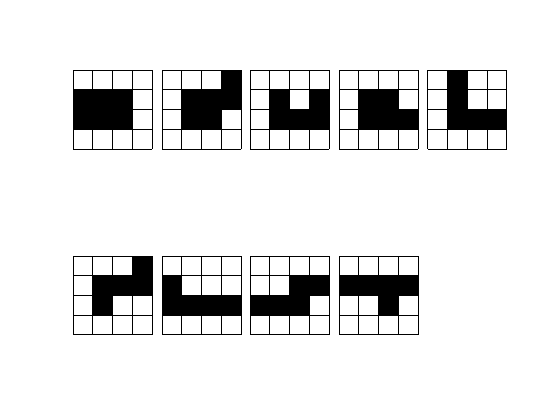


%% Pieces shape
% 9 pieces, start in a 5x5 empty space
NoPuzzlePieces = 9;
PuzzlePieces = repmat({false(5,5)},NoPuzzlePieces,8);
PuzzlePiecesBlockNo = zeros(NoPuzzlePieces,1);

% □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□
% ■■■□□ % □■■□□ % □■■■□ % □■■■□ % □■■■□ % □■□□□ % ■■■■□ % ■■■□□ % □□■□□
% ■■■□□ % □■■■□ % □■□■□ % □■■□□ % □■□□□ % □■■■□ % ■□□□□ % □□■■□ % ■■■■□
% □□□□□ % □□□■□ % □□□□□ % □□□□□ % □■□□□ % □□□■□ % □□□□□ % □□□□□ % □□□□□
% □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□ % □□□□□

PuzzlePieces{1,1}(2:3,1:3)=true;
PuzzlePieces{2,1}(2:3,2:3)=true;PuzzlePieces{2,1}(3:4,4)=true;
PuzzlePieces{3,1}(2,2:4)=true;PuzzlePieces{3,1}(3,[2,4])=true;
PuzzlePieces{4,1}(2,2:4)=true;PuzzlePieces{4,1}(3,2:3)=true;
PuzzlePieces{5,1}(2,2:4)=true;PuzzlePieces{5,1}(3:4,2)=true;
PuzzlePieces{6,1}(2,2)=true;PuzzlePieces{6,1}(3,2:4)=true;PuzzlePieces{6,1}(4,4)=true;
PuzzlePieces{7,1}(2,1:4)=true;PuzzlePieces{7,1}(3,1)=true;
PuzzlePieces{8,1}(2,1:3)=true;PuzzlePieces{8,1}(3,3:4)=true;
PuzzlePieces{9,1}(2,3)=true;PuzzlePieces{9,1}(3,1:4)=true;

for n=1:NoPuzzlePieces
    PuzzlePiecesBlockNo(n) = sum(PuzzlePieces{n,1},'all');
end

if true
    MaxNperRow = 5;
    NRow = ceil(NoPuzzlePieces/MaxNperRow);
    H2 = tiledlayout(NRow,MaxNperRow,'TileSpacing','compact','Padding','loose');
    for i=1:NoPuzzlePieces
        nexttile
        H20 = pcolor(~PuzzlePieces{i});
        colormap(gray(2));
        set(gca, 'xticklabel', [], 'yticklabel', []);
        axis square
    end
end

## **Choose the Date:**

% Flip Vertical, Flip Horizontal, Roate(counterclockwise) 90
% [Boolean number, Boolean number, Boolean number]
for n=1:NoPuzzlePieces
    for i=0:1:7
        temp = PuzzlePieces{n,1};
        binstr = dec2bin(i,3)=='1';
        if binstr(3)
            temp = flip(temp);
        end
        if binstr(2)
            temp = flip(temp,2);
        end
        if binstr(1)
            temp = rot90(temp);
        end
        PuzzlePieces{n,i+1} = temp;
    end
end

%% Qusetion
Year = "2025";
Month = 8;
Day = 23;
Week = 4;
Year = int32(str2num(Year));
if ~isempty(Year)
    [DayNumber,~] = weekday([num2str(Month,'%02d'),'/',num2str(Day,'%02d'),'/',num2str(Year,'%04d')]);
    if DayNumber==1
        Week = 7;
    else
        Week = DayNumber-1;
    end
end
Week2String = ['Mon';'Tue';'Wed';'Thu';'Fri';'Sat';'Sun'];
FrameQuestion = LEGO_IDEAS_DailyPuzzle(Month,Day,Week);
filename = ['output/Result_', date2String(Month,Day), '(', Week2String(Week,:), ')','.txt'];
if ~isfolder('output')
    mkdir('output');
end

Frame = FrameDefault | FrameQuestion;

%% Initalization
SizeFrame = size(Frame);
ExpandedFrame = true(SizeFrame(1)+4, SizeFrame(2)+4);
ExpandedFrame(3:SizeFrame(1)+2,3:SizeFrame(2)+2) = Frame;
LN = SizeFrame(1)*SizeFrame(2)*8;

ExpandedPuzzlePieces = repmat({false(SizeFrame(1),SizeFrame(2))},NoPuzzlePieces,LN);
ExpandedPuzzlePiecesFlag = false(NoPuzzlePieces,LN);
for i=1:NoPuzzlePieces
    for L0=1:LN
        R0 = ceil(L0/8);
        P0 = rem(L0,8);
        if P0==0
            P0 = 8;
        end
        R0x = ceil(R0/SizeFrame(2));
        R0y = rem(R0,SizeFrame(2));
        if R0y==0
            R0y = SizeFrame(2);
        end
        tempFrame = false(SizeFrame(1)+4, SizeFrame(2)+4);
        tempFrame(R0x:R0x+4,R0y:R0y+4) = PuzzlePieces{i,P0};
        OverlayFrame = tempFrame & ExpandedFrame;
        if sum(OverlayFrame,'all')==0
            ExpandedPuzzlePieces{i,L0} = tempFrame(3:SizeFrame(1)+2,3:SizeFrame(2)+2);
            ExpandedPuzzlePiecesFlag(i,L0) = true;
        end
    end
end
ValuableDigit = ~reshape(FrameDefault,1,[]);
for i=1:NoPuzzlePieces
    tempIndex = zeros(1,LN);
    for L0=1:LN
        % treat matrix of [0,1] as binary
        reshapeMatrix = reshape(ExpandedPuzzlePieces{i,L0},1,[]);
        binValue = num2str(reshapeMatrix(ValuableDigit));
        tempIndex(1,L0) = bin2dec(binValue);
    end
    [~, UniqueIndex, ~] = unique(tempIndex);
    tempFlag = false(1,LN);
    tempFlag(UniqueIndex) = true;
    ExpandedPuzzlePiecesFlag(i,:) = ExpandedPuzzlePiecesFlag(i,:) & tempFlag;
end

FindAllAnswer = false;
IsOutput = false;
IsMerge = false;
MaxNumberOfSolutions = 100;

* Install Ghostscript (https://www.ghostscript.com/releases/gsdnld.html) if you want to merge pdf files.

Solution_all = [];

NoBlocks = SizeFrame(1)*SizeFrame(2);
MaxIndex = sum(ExpandedPuzzlePiecesFlag,'all') + 1;
ExactCoverMatrix = false(MaxIndex, NoBlocks + NoPuzzlePieces + 1);
% raw: all possible positions of the puzzle pieces; FrameQuestion
% column: each block of the puzzle is filled; each piece is chosen; Question is solved

% FrameQuestion
ExactCoverMatrix(end,:) = [reshape(Frame, 1, NoBlocks), false(1,NoPuzzlePieces), true];
% Each possible positions of the puzzle pieces
IndexofPuzzlePieces = cell(1,sum(ExpandedPuzzlePiecesFlag,'all'));
Index_temp = 0;
for i=1:NoPuzzlePieces
    for j=1:LN
        if ExpandedPuzzlePiecesFlag(i,j)
            Index_temp = Index_temp+1;
            IndexofPuzzlePieces{Index_temp} = [i,j];
            ExactCoverMatrix(Index_temp,1:NoBlocks) = reshape(ExpandedPuzzlePieces{i,j}, 1, NoBlocks);
            ExactCoverMatrix(Index_temp,NoBlocks+i) = true;
        end
    end
end

u = 1:size(ExactCoverMatrix,2);
s = cell(1,size(ExactCoverMatrix,1));
for i=1:size(ExactCoverMatrix,1)
    s{i} = find(ExactCoverMatrix(i,:));
end
Sol = AlgorithmX(u,s,~FindAllAnswer);

if ~isempty(Sol)
    N_sol = min(MaxNumberOfSolutions,length(Sol));
    Solution_all = zeros(N_sol,12);
    for i=1:N_sol
        Solution_one = Sol{i};
        for j=1:length(Solution_one)
            if Solution_one(j)<MaxIndex
                Index = IndexofPuzzlePieces{Solution_one(j)};
                Solution_all(i,Index(1)) = Index(2);
            end
        end
    end
else
    N_sol = 0;
end

if ~FindAllAnswer && N_sol>0
    Solution_onlyOne = Solution_all(ceil(rand*N_sol),:);
else
    Solution_onlyOne = [];
end

fprintf(' \n');

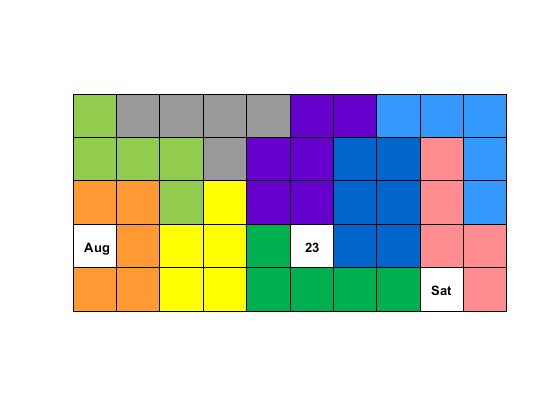

%% Output

ColorMaps = [1 1 1; 0 0.4 0.8; 0.4 0 0.8; 1 0.6 0.2; 1 1 0; 1 0 0; 0.2 0.6 1; 0.57 0.8 0.31; 0 0.69 0.31; 1 0.55 0.56; 0.6 0.6 0.6];
NRow = 5;
NColumn = 4;
NImage = NRow*NColumn;
if ~FindAllAnswer
    if Solution_onlyOne(1)>0
        HeatMapMatrix = zeros(SizeFrame(1), SizeFrame(2));
        for n=1:NoPuzzlePieces
            HeatMapMatrix = HeatMapMatrix + n.*ExpandedPuzzlePieces{n,Solution_onlyOne(n)};
        end
        HeatMapMatrix = HeatMapMatrix + (NoPuzzlePieces+1).*FrameDefault;
        temp_HeatMapMatrix = [flip(HeatMapMatrix), zeros(size(HeatMapMatrix,1),1); zeros(1,size(HeatMapMatrix,2)+1)];
        figure;
        H0 = pcolor(temp_HeatMapMatrix);
        colormap(ColorMaps);
        axis equal
        ylim([1 6])
        set(gca, 'xticklabel', [], 'yticklabel', [])
        labelTable(HeatMapMatrix, Text_Frame)
        if IsOutput
            titlename = ['Solution of ', date2String(Month,Day), ' (', Week2String(Week,:), ') (randomly chosen)'];
            title(titlename);
            PrintFileName = ['output/Solution_', date2String(Month,Day), '(', Week2String(Week,:), ')_RandomChosen.pdf'];
            print(gcf,PrintFileName,'-dpdf','-bestfit'); %PDF
%             close all
        end
    else
        fprintf('No solution was found for Daily Puzzle on %s.\n', date2String(Month,Day));
    end
else
    ImageNumber = N_sol;
    if ImageNumber>0
    fprintf('Daily Puzzle on %s(%s) solved, %d solution(s) found.\n', date2String(Month,Day),Week2String(Week,:), length(Sol));
    fprintf('Exporting pdf files, don''t close the windows showing up...........');
    HeatMapMatrix = cell(ImageNumber,1);
    for i=1:ImageNumber
        HeatMapMatrix{i} = zeros(SizeFrame(1), SizeFrame(2));
        for n=1:NoPuzzlePieces
            HeatMapMatrix{i} = HeatMapMatrix{i} + n.*ExpandedPuzzlePieces{n,Solution_all(i,n)};
        end
        HeatMapMatrix{i} = HeatMapMatrix{i} + (NoPuzzlePieces+1).*FrameDefault;
    end

    NPage = ceil(ImageNumber/NImage);
    PrintFileName = cell(NPage,1);
    for p=1:NPage
        H0 = tiledlayout(NRow,NColumn,'TileSpacing','compact','Padding','loose');
        for i=1:min(NImage,ImageNumber-(p-1)*NImage)
            n = (p-1)*NImage+i;
            nexttile
            H = heatmap(HeatMapMatrix{n},'Colormap',ColorMaps,'CellLabelColor','none');
            H.Position = [0.13,0.11,0.775,0.815];
            H.ColorbarVisible = 'off';
            H.XDisplayLabels = nan(size(H.XDisplayData));
            H.YDisplayLabels = nan(size(H.YDisplayData));
        end
        titlename = ['Solution of ', date2String(Month,Day), ' (', Week2String(Week,:), ') Page', num2str(p,'%02d')];
        title(H0, titlename);
        set(gcf,'Position',[160 80 1480 880]);
        %H0.Visible = 'off';
        orient(gcf,'landscape')
        if p==1 && IsMerge
            PrintFileName{p,1} = ['output/Solution_', date2String(Month,Day), '(', Week2String(Week,:), ').pdf'];
        else
            PrintFileName{p,1} = ['output/Solution_', date2String(Month,Day), '(', Week2String(Week,:), ')_P', num2str(p,'%02d'), '.pdf'];
        end
        print(gcf,PrintFileName{p,1},'-dpdf','-bestfit'); %PDF
        close all
    end

    if NPage>1 && IsMerge
        append_pdfs_edit(PrintFileName');
        for i=2:NPage
            delete(PrintFileName{i,1});
        end
    end
    fprintf('   Done!\n');

    end
end


 
%% Function

function [frame_question] = LEGO_IDEAS_DailyPuzzle(Month,Day,Week)
    frame_question = false(5,10);
    if Month<=3
        frame_question(1,Month) = true;
    elseif Month<=5
        frame_question(2,Month-3) = true;
    elseif Month<=7
        frame_question(3,Month-5) = true;
    elseif Month<=9
        frame_question(4,Month-7) = true;
    else
        frame_question(5,Month-9) = true;
    end

    if Day<=5
        frame_question(1,Day+3) = true;
    elseif Day<=12
        frame_question(2,Day-5+2) = true;
    elseif Day<=19
        frame_question(3,Day-12+2) = true;
    elseif Day<=26
        frame_question(4,Day-19+2) = true;
    else
        frame_question(5,Day-26+3) = true;
    end
    
    switch Week
        case 1
            frame_question(1,9) = true;
        case 2
            frame_question(1,10) = true;
        case 3
            frame_question(2,10) = true;
        case 4
            frame_question(3,10) = true;
        case 5
            frame_question(4,10) = true;
        case 6
            frame_question(5,9) = true;
        case 7
            frame_question(5,10) = true;
    end
end

function [] = labelTable(Frame, TextFrame)
    row = size(Frame,1);
    column = size(Frame,2);
    for i=1:row
        for j=1:column
            if Frame(i,j)==0
                shiftx = 0.25+0.1*(3-length(TextFrame{i,j}));
                text(j+shiftx, row+1.5-i, TextFrame{i,j}, 'FontWeight', 'bold');
            end
        end
    end
end

function [StringDate] = date2String(Month, Day)
    switch Month
        case 1
            StringDate1 = 'Jan';
        case 2
            StringDate1 = 'Feb';
        case 3
            StringDate1 = 'Mar';
        case 4
            StringDate1 = 'Apr';
        case 5
            StringDate1 = 'May';
        case 6
            StringDate1 = 'Jun';
        case 7
            StringDate1 = 'Jul';
        case 8
            StringDate1 = 'Aug';
        case 9
            StringDate1 = 'Sep';
        case 10
            StringDate1 = 'Oct';
        case 11
            StringDate1 = 'Nov';
        case 12
            StringDate1 = 'Dec';
    end
    switch Day
        case 1
            StringDate2 = '01st';
        case 2
            StringDate2 = '02nd';
        case 3
            StringDate2 = '03rd';
        case 21
            StringDate2 = '21st';
        case 22
            StringDate2 = '22nd';
        case 23
            StringDate2 = '23rd';
        case 31
            StringDate2 = '31st';
        otherwise
            StringDate2 = [num2str(Day,'%02d'), 'th'];
    end
    StringDate = [StringDate1, '-', StringDate2];
end

%% https://www.mathworks.com/matlabcentral/cody/problems/56588-exact-cover/solutions
%% Problem 56588. Exact Cover, Solution 10165687
%% Submitted on 17 Dec 2022 by Tim
%% Knuth's Algorithm X (utilizing the Dancing Links technique)

function x=AlgorithmX(u,s,flag)
    Q=cellfun(@(t)ismember(u',t),s,'uni',0);
    x=excov(cell2mat(Q),1:numel(s));
    if length(x)>0 && flag
        return
    end
end
   
function S=excov(Q,L)
S={};
[~,i]=min(sum(Q,2));
for j=find(Q(i,:))
   if all(Q(:,j))
      S=[S L(j)];
   else
      J=~any(Q(Q(:,j),:),1);
      T=excov(Q(~Q(:,j),J),L(J));
      for m=1:numel(T)
         S=[S [L(j) T{m}]];
      end
   end
end
end

%APPEND_PDFS Appends/concatenates multiple PDF files
%
% Example:
%   append_pdfs(output, input1, input2, ...)
%   append_pdfs(output, input_list{:})
%   append_pdfs test.pdf temp1.pdf temp2.pdf
%
% This function appends multiple PDF files to an existing PDF file, or
% concatenates them into a PDF file if the output file doesn't yet exist.
%
% This function requires that you have ghostscript installed on your
% system. Ghostscript can be downloaded from: http://www.ghostscript.com
%
% IN:
%    output - string of output file name (including the extension, .pdf).
%             If it exists it is appended to; if not, it is created.
%    input1 - string of an input file name (including the extension, .pdf).
%             All input files are appended in order.
%    input_list - cell array list of input file name strings. All input
%                 files are appended in order.

% Copyright: Oliver Woodford, 2011

% Thanks to Reinhard Knoll for pointing out that appending multiple pdfs in
% one go is much faster than appending them one at a time.

% Thanks to Michael Teo for reporting the issue of a too long command line.
% Issue resolved on 5/5/2011, by passing gs a command file.

% Thanks to Martin Wittmann for pointing out the quality issue when
% appending multiple bitmaps.
% Issue resolved (to best of my ability) 1/6/2011, using the prepress
% setting

% modified
function append_pdfs_edit(varargin)
% Are we appending or creating a new file
varargin = varargin{1};
append = exist(varargin{1}, 'file') == 2;
if append
    output = [tempname '.pdf'];
else
    output = varargin{1};
    varargin = varargin(2:end);
end
% Create the command file
cmdfile = [tempname '.txt'];
fh = fopen(cmdfile, 'w');
fprintf(fh, '-q -dNOPAUSE -dBATCH -sDEVICE=pdfwrite -dPDFSETTINGS=/prepress -sOutputFile="%s" -f', output);
fprintf(fh, ' "%s"', varargin{:});
fclose(fh);
% Call ghostscript
ghostscript(['@"' cmdfile '"']);
% Delete the command file
delete(cmdfile);
% Rename the file if needed
if append
    movefile(output, varargin{1});
end
end

function varargout = ghostscript(cmd)
%GHOSTSCRIPT  Calls a local GhostScript executable with the input command
%
% Example:
%   [status result] = ghostscript(cmd)
%
% Attempts to locate a ghostscript executable, finally asking the user to
% specify the directory ghostcript was installed into. The resulting path
% is stored for future reference.
% 
% Once found, the executable is called with the input command string.
%
% This function requires that you have Ghostscript installed on your
% system. You can download this from: http://www.ghostscript.com
%
% IN:
%   cmd - Command string to be passed into ghostscript.
%
% OUT:
%   status - 0 iff command ran without problem.
%   result - Output from ghostscript.

% Copyright: Oliver Woodford, 2009-2010

% Thanks to Jonas Dorn for the fix for the title of the uigetdir window on
% Mac OS.

% Thanks to Nathan Childress for the fix to the default location on 64-bit
% Windows systems.

% 27/4/11 - Find 64-bit Ghostscript on Windows. Thanks to Paul Durack and
% Shaun Kline for pointing out the issue

% 4/5/11 - Thanks to David Chorlian for pointing out an alternative
% location for gs on linux.

% Call ghostscript
[varargout{1:nargout}] = system(sprintf('"%s" %s', gs_path, cmd));
return
end

function path = gs_path
% Return a valid path
% Start with the currently set path
path = user_string('ghostscript');
% Check the path works
if check_gs_path(path)
    return
end
% Check whether the binary is on the path
if ispc
    bin = {'gswin32c.exe', 'gswin64c.exe'};
else
    bin = {'gs'};
end
for a = 1:numel(bin)
    path = bin{a};
    if check_store_gs_path(path)
        return
    end
end
% Search the obvious places
if ispc
    default_location = 'C:\Program Files\gs\';
    dir_list = dir(default_location);
    if isempty(dir_list)
        default_location = 'C:\Program Files (x86)\gs\'; % Possible location on 64-bit systems 
        dir_list = dir(default_location);
    end
    executable = {'\bin\gswin32c.exe', '\bin\gswin64c.exe'};
    ver_num = 0;
    % If there are multiple versions, use the newest
    for a = 1:numel(dir_list)
        ver_num2 = sscanf(dir_list(a).name, 'gs%g');
        if ~isempty(ver_num2) && ver_num2 > ver_num
            for b = 1:numel(executable)
                path2 = [default_location dir_list(a).name executable{b}];
                if exist(path2, 'file') == 2
                    path = path2;
                    ver_num = ver_num2;
                end
            end
        end
    end
    if check_store_gs_path(path)
        return
    end
else
    bin = {'/usr/bin/gs', '/usr/local/bin/gs'};
    for a = 1:numel(bin)
        path = bin{a};
        if check_store_gs_path(path)
            return
        end
    end
end
% Ask the user to enter the path
while 1
    if strncmp(computer, 'MAC', 3) % Is a Mac
        % Give separate warning as the uigetdir dialogue box doesn't have a
        % title
        uiwait(warndlg('Ghostscript not found. Please locate the program.'))
    end
    base = uigetdir('/', 'Ghostcript not found. Please locate the program.');
    if isequal(base, 0)
        % User hit cancel or closed window
        break;
    end
    base = [base filesep];
    bin_dir = {'', ['bin' filesep], ['lib' filesep]};
    for a = 1:numel(bin_dir)
        for b = 1:numel(bin)
            path = [base bin_dir{a} bin{b}];
            if exist(path, 'file') == 2
                if check_store_gs_path(path)
                    return
                end
            end
        end
    end
end
error('Ghostscript not found. Have you installed it from www.ghostscript.com?');
end

function good = check_store_gs_path(path)
% Check the path is valid
good = check_gs_path(path);
if ~good
    return
end
% Update the current default path to the path found
if ~user_string('ghostscript', path)
    warning('Path to ghostscript installation could not be saved. Enter it manually in ghostscript.txt.');
    return
end
return
end

function good = check_gs_path(path)
% Check the path is valid
[good message] = system(sprintf('"%s" -h', path));
good = good == 0;
return
end

%USER_STRING  Get/set a user specific string
%
% Examples:
%   string = user_string(string_name)
%   saved = user_string(string_name, new_string)
%
% Function to get and set a string in a system or user specific file. This
% enables, for example, system specific paths to binaries to be saved.
%
% IN:
%   string_name - String containing the name of the string required. The
%                 string is extracted from a file called (string_name).txt,
%                 stored in the same directory as user_string.m.
%   new_string - The new string to be saved under the name given by
%                string_name.
%
% OUT:
%   string - The currently saved string. Default: ''.
%   saved - Boolean indicating whether the save was succesful

% Copyright (C) Oliver Woodford 2011

% This method of saving paths avoids changing .m files which might be in a
% version control system. Instead it saves the user dependent paths in
% separate files with a .txt extension, which need not be checked in to
% the version control system. Thank you to Jonas Dorn for suggesting this
% approach.

function string = user_string(string_name, string)
if ~ischar(string_name)
    error('string_name must be a string.');
end
% Create the full filename
string_name = fullfile(fileparts(mfilename('fullpath')), '.ignore', [string_name '.txt']);
if nargin > 1
    % Set string
    if ~ischar(string)
        error('new_string must be a string.');
    end
    % Make sure the save directory exists
    dname = fileparts(string_name);
    if ~exist(dname, 'dir')
        % Create the directory
        try
            if ~mkdir(dname)                
                string = false;
                return
            end
        catch
            string = false;
            return
        end
        % Make it hidden
        try
            fileattrib(dname, '+h');
        catch
        end
    end
    % Write the file
    fid = fopen(string_name, 'w');
    if fid == -1
        string = false;
        return
    end
    try
        fwrite(fid, string, '*char');
    catch
        fclose(fid);
        string = false;
        return
    end
    fclose(fid);
    string = true;
else
    % Get string
    fid = fopen(string_name, 'r');
    if fid == -1
        string = '';
        return
    end
    string = fread(fid, '*char')';
    fclose(fid);
end
return
end